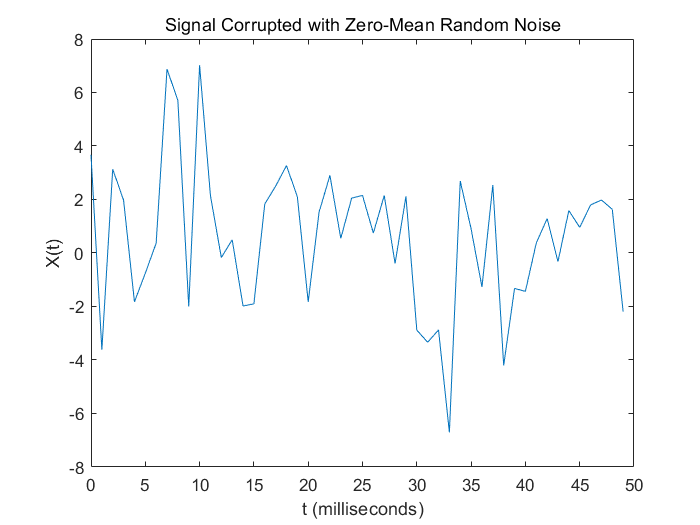

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector


S = 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);
X = S + 2*randn(size(t));

plot(1000*t(1:50),X(1:50))
title('Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')

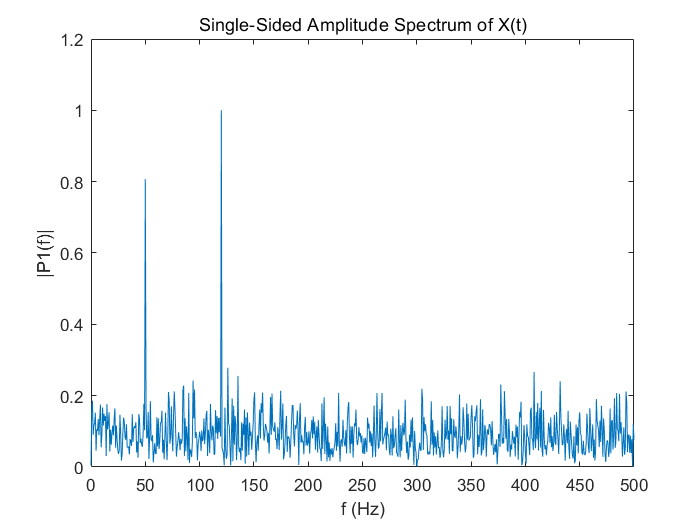


Y = fft(X);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
% 计算双侧频谱 P2。然后基于 P2 和偶数信号长度 L 计算单侧频谱 P1

f = Fs*(0:(L/2))/L;
% 定义频域 f 并绘制单侧幅值频谱 P1。
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

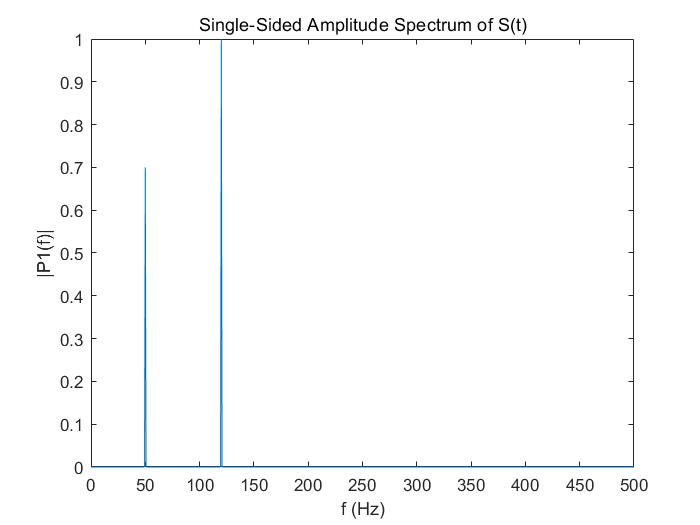


Y = fft(S);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

plot(f,P1) 
title('Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')